# Star Tracker

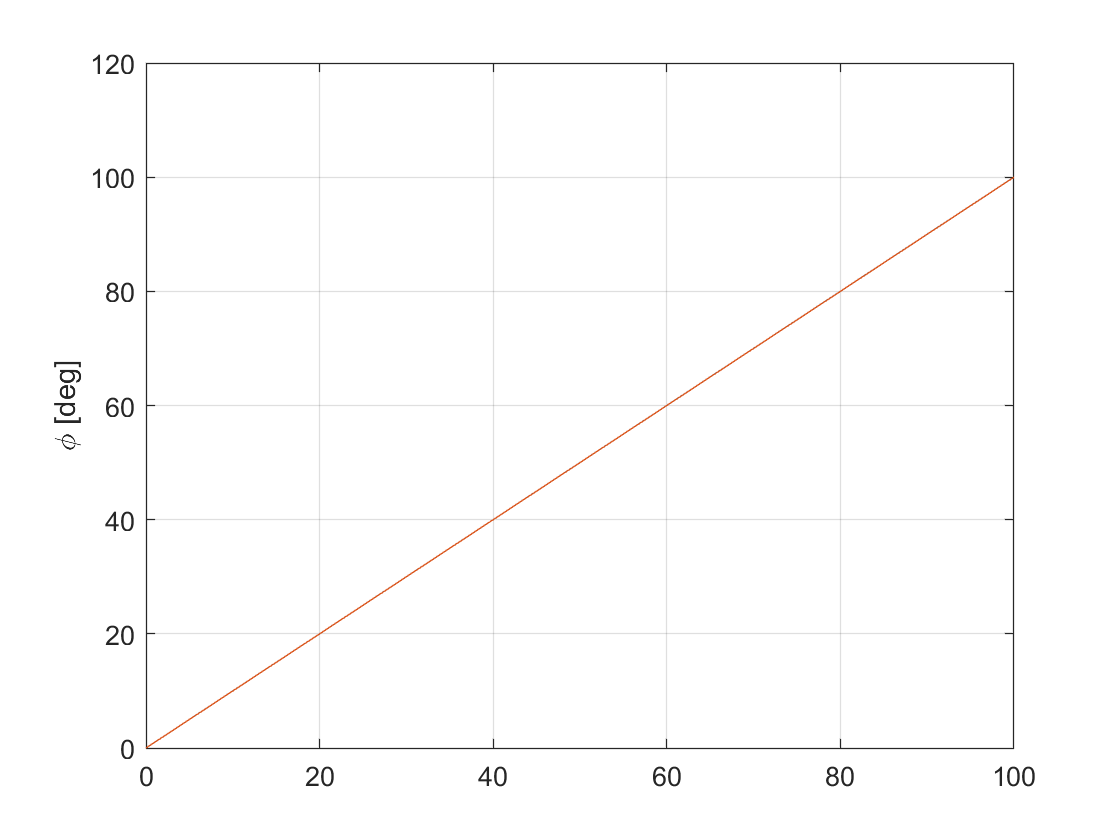

%--- star tracker ------------------------------------------------------%
clear 
close all

t  = 100;
dt = 1;
time = 0:dt:t;


% measurement noise
sig_xy = (1/3600)*(pi/180); % deg
sig_z  = (5/3600)*(pi/180); % deg

phi = time*(pi/180);
theta = 30*ones(length(time),1)*(pi/180);
psi = 10*ones(length(time),1)*(pi/180);


P1 = zeros(1,1000);
P2 = zeros(1,1000);
P = zeros(1,1000);

for i=1:1000
q = angle2quat(phi,theta,psi);

q_hat1 = startracker(q,dt);
q_hat2 = startracker(q,dt);

[phi_hat1, theta_hat1, psi_hat1] = quat2angle(q_hat1);
[phi_hat2, theta_hat2, psi_hat2] = quat2angle(q_hat2);

phi_hat = [1/sig_xy^2 1/sig_xy^2]*[phi_hat1 phi_hat2]'./(1/sig_xy^2+1/sig_xy^2);


P1(i) = phi_hat1(end);
P(i) = phi_hat(end);

end

figure
plot(time,phi_hat*(180/pi),time,phi*(180/pi))
ylabel('\phi [deg]')
grid

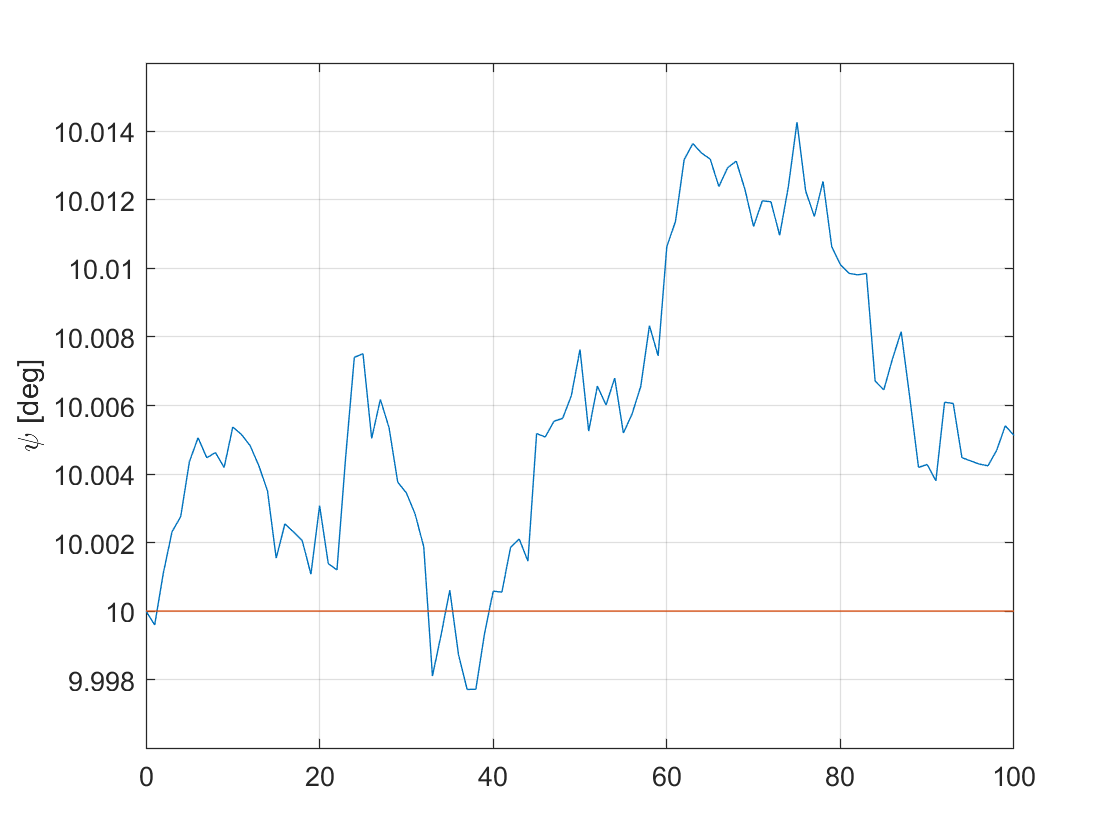

figure
plot(time,psi_hat1*(180/pi),time,psi*(180/pi))
ylabel('\psi [deg]')
grid

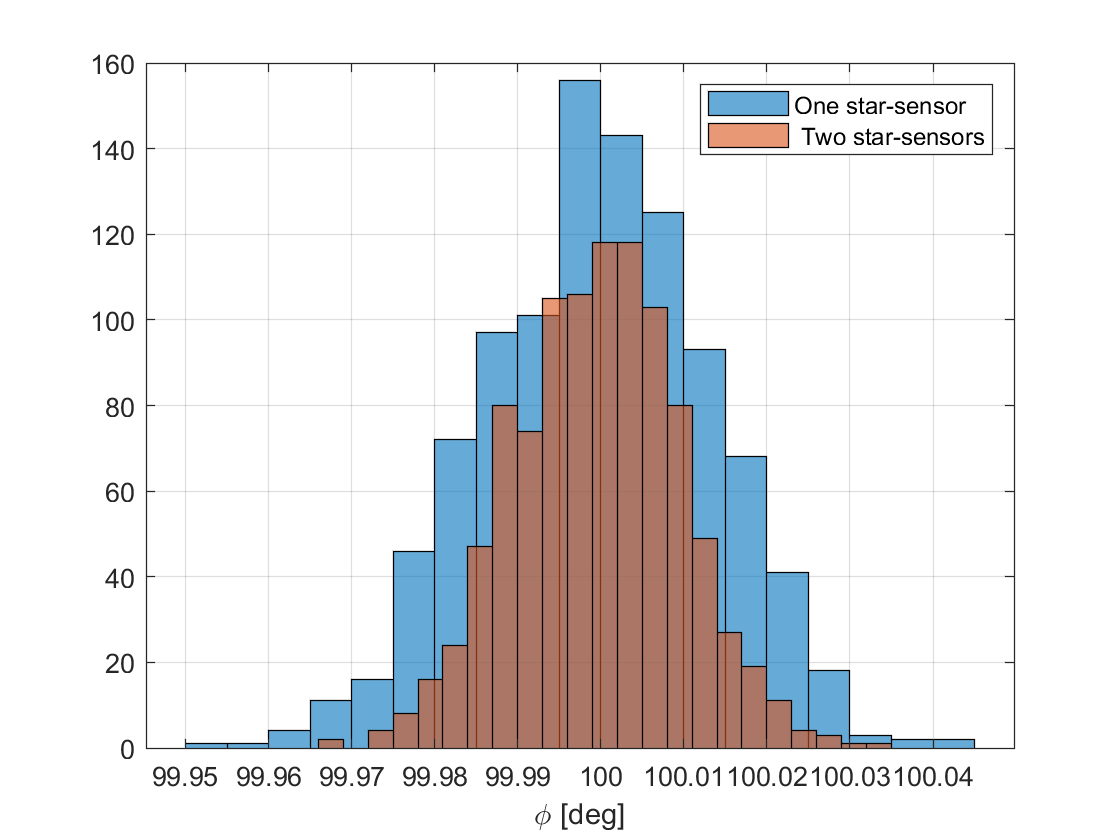

figure
histogram(P1*(180/pi))
hold on
histogram(P*(180/pi))
legend('One star-sensor',' Two star-sensors')
xlabel('\phi [deg]')
grid on

% fusion of 2 star trackers => sig_new^2= sig_old^2/2 (if same sensors)



## Gyro

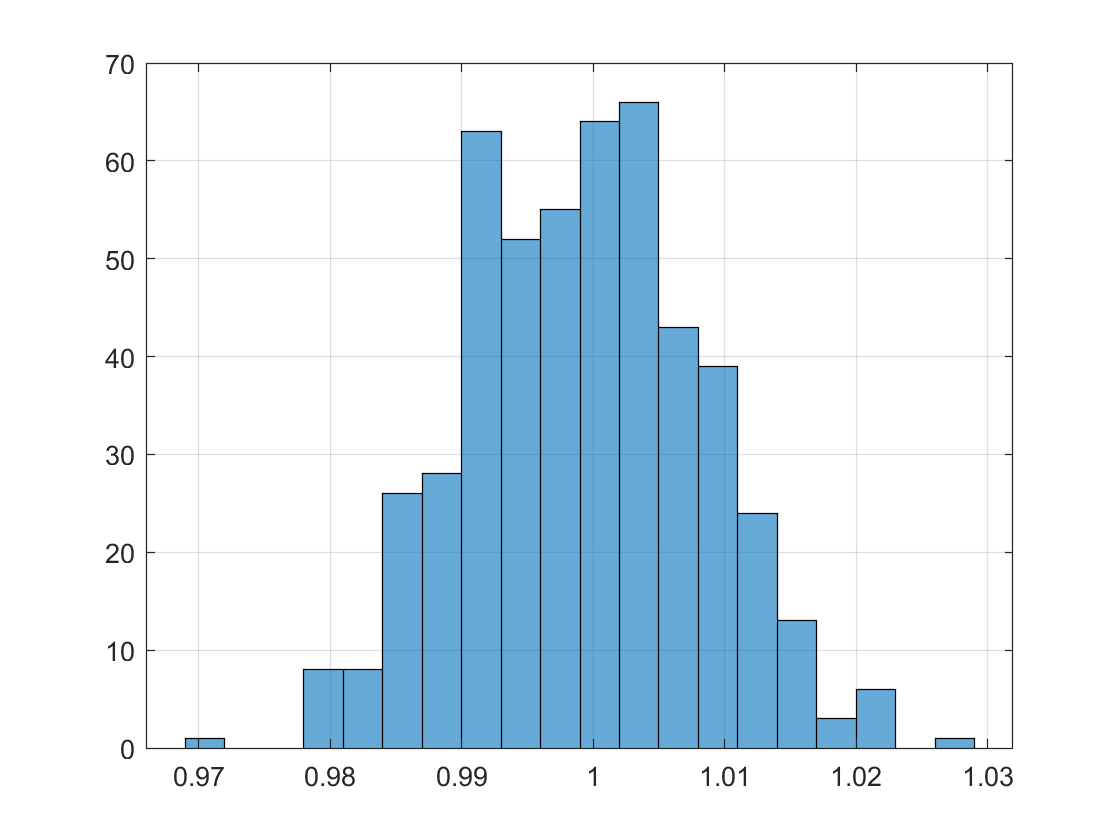

%---- gyro ----------------------------------------------------------%
clear 
close all

t  = 100;
dt = 0.01;
time = 0:dt:t;
omega = [ones(1,length(time)); ones(1,length(time)); zeros(1,length(time))];
P=zeros(1,500);

for i=1:500
omega_hat = gyro(omega,dt);
P(i) = omega_hat(1,end);
end

figure
histogram(P)
grid on

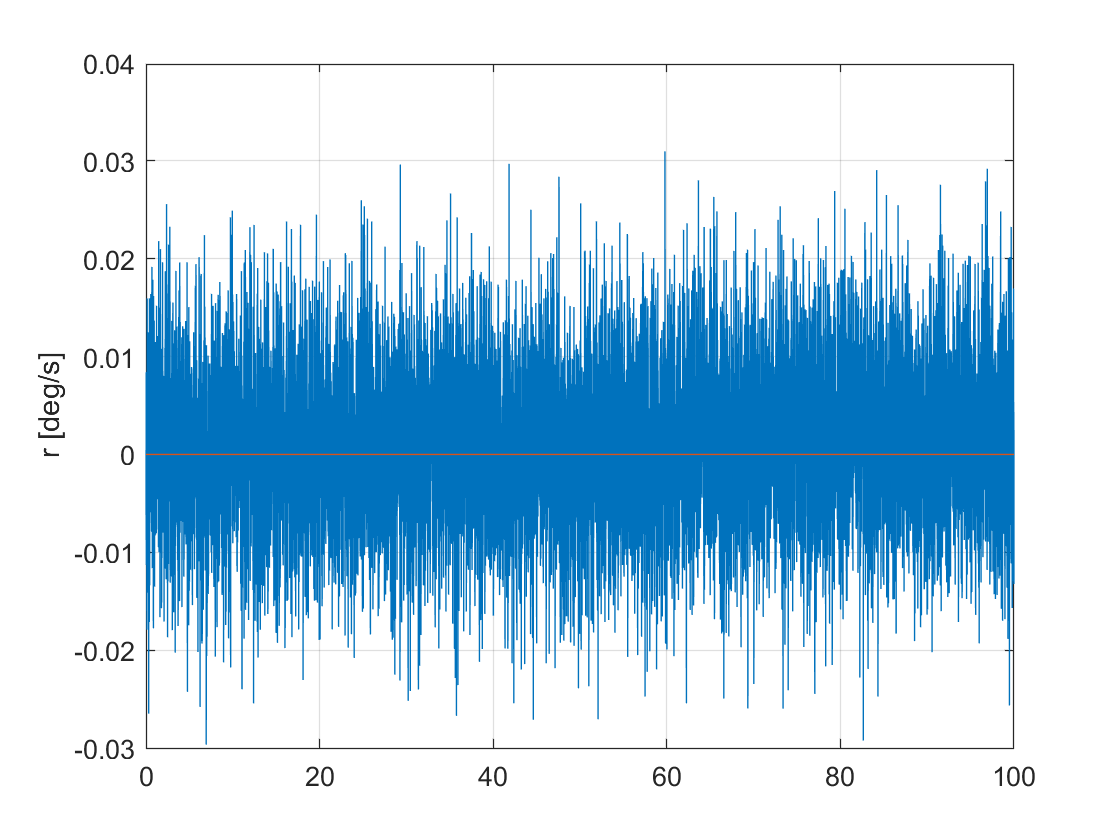


figure
plot(time,omega_hat(3,:),time,omega(3,:))
ylabel('r [deg/s]')
grid

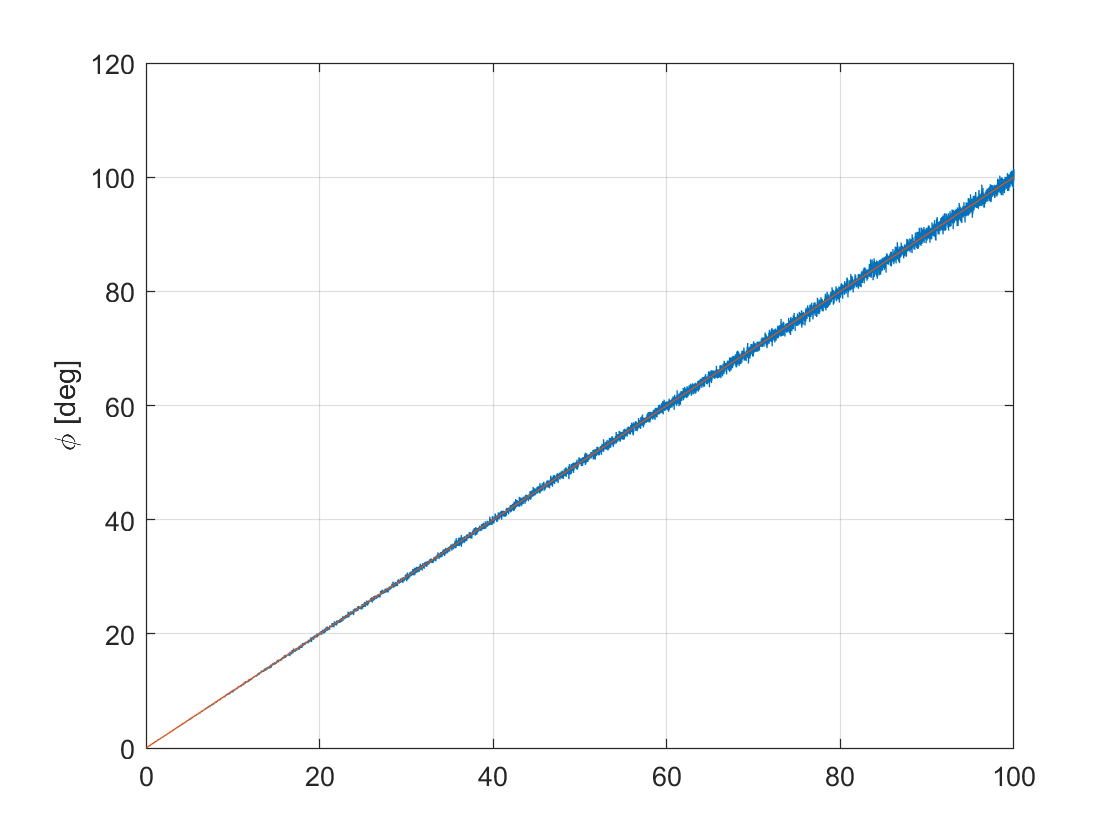


figure
[phi_hat, ~, psi_hat] = dcm(omega_hat*(pi/180),dt);
plot(time,omega_hat(1,:).*time,time,omega(1,:).*time)
ylabel('\phi [deg]')
grid

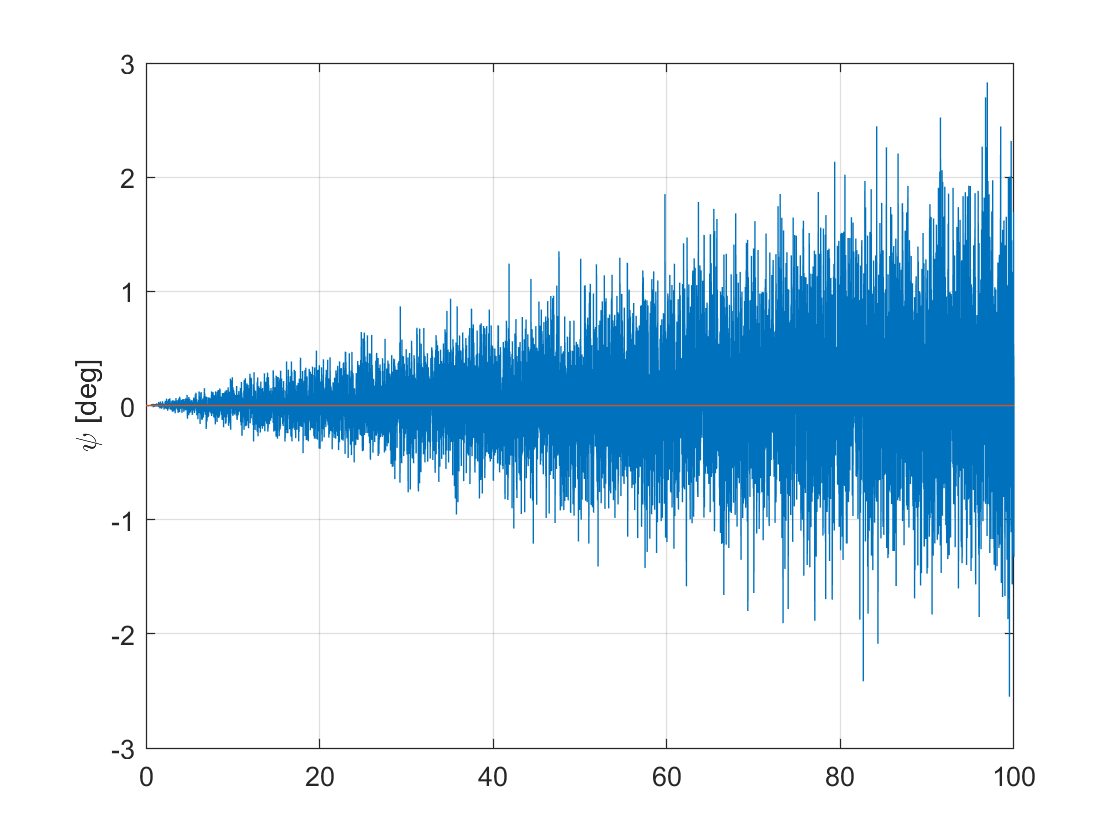


figure
plot(time,omega_hat(3,:).*time,time,omega(3,:).*time)
ylabel('\psi [deg]')
grid

function [q_hat]= startracker(q,dt)

[phi, theta, psi] = quat2angle(q);

% measurement noise
sig_xy = (1/3600)*(pi/180); % rad
sig_z  = (5/3600)*(pi/180); % rad

 bxy = zeros(length(phi),1);
 bz  = zeros(length(phi),1);

for i=2:length(bz)
   bxy(i)= bz(i-1)+sig_xy*sqrt(dt)*randn();
   bz(i) = bz(i-1)+sig_z*sqrt(dt)*randn(); 
end

% Low frq errors 
dphi   = zeros(length(phi),1);
dtheta = zeros(length(phi),1);
dpsi   = zeros(length(phi),1);

% euler_hat = euler + b + deuler 
phi_hat    = phi + bxy + dphi ;
theta_hat  = theta + bxy + dtheta ;
psi_hat    = psi + bz + dpsi ;


q_hat = angle2quat(phi_hat,theta_hat,psi_hat);

end



function [x_hat] = gyro(x,dt)
% b ~ N(b0, seg_b^2) : constant bias error
sig_b = 0.5/3600;
% nu WGN ; PSD = seg_nu^2
sig_nu = 0.05/60;
% s ~ N(s0, seg_s^2) 
S = diag([0.1/100 0.1/100 0.1/100]);% 1000ppm = 0.1%

b0 = 0;
b = b0*ones(3,length(x));
for i=2:length(x)
   b(:,i)=b(:,i-1)+sig_b*sqrt(dt)*randn(3,1);
end

x_hat=x;
for i=2:length(x)
   x_hat(:,i)= (eye(3)-S)*x(:,i) + 0.5*(b(:,i)+b(:,i-1))+sqrt(sig_nu^2/dt +sig_b^2*(dt/12))*randn(3,1);
end

end 


function [phi, theta, psi] = quat(w,dt)
phi   = zeros(1,length(w));
theta = zeros(1,length(w));
psi   = zeros(1,length(w));
q0 = [1 0 0 0]';
for i=1:length(w)
  h = dt;
  Q = [0 -w(:,i)'; 
       w(1,i) 0 w(3,i) -w(2,i);
       w(2,i) -w(3,i) 0 w(1,i);
       w(3,i) w(2,i) -w(1,i) 0];
  q = ( cos(0.5*h*norm(w(:,i)))*eye(4) + (sin(0.5*h*norm(w(:,i)))/norm(w(:,i)))*Q )*q0;
  q0 = q;
  psi(i)  = (atan2(2*(q(2)*q(3)+q(1)*q(4)),1-2*(q(3)^2+q(4)^2))) ;
  theta(i)= (-asin(2*(q(2)*q(4)-q(1)*q(3))));
  phi(i)  = (atan2(2*(q(1)*q(2)+q(3)*q(4)),1-2*(q(2)^2+q(3)^2)));
end
end


function [phi, theta, psi]=dcm(w,dt)
phi   = zeros(1,length(w));
theta = zeros(1,length(w));
psi   = zeros(1,length(w));
% poisson kinematic equations 
R0 = eye(3);
for i=1:length(w)
  h = dt;  
  Omega = [0 -w(3,i) w(2,i); w(3,i) 0 -w(1,i); -w(2,i) w(1,i) 0];  
  R  = R0*(eye(3) + (sin(h*norm(w(:,i)))/norm(w(:,i)))*Omega +((1-cos(h*norm(w(:,i))))/(norm(w(:,i))^2))*(Omega^2));
  R0 = R;
  psi(i)   = (atan2(R(2,1),R(1,1)));
  theta(i) = (-asin(R(3,1)));
  phi(i)   = (atan2(R(3,2),R(3,3)));
end
end
